**from periodic to aperiodic signal**

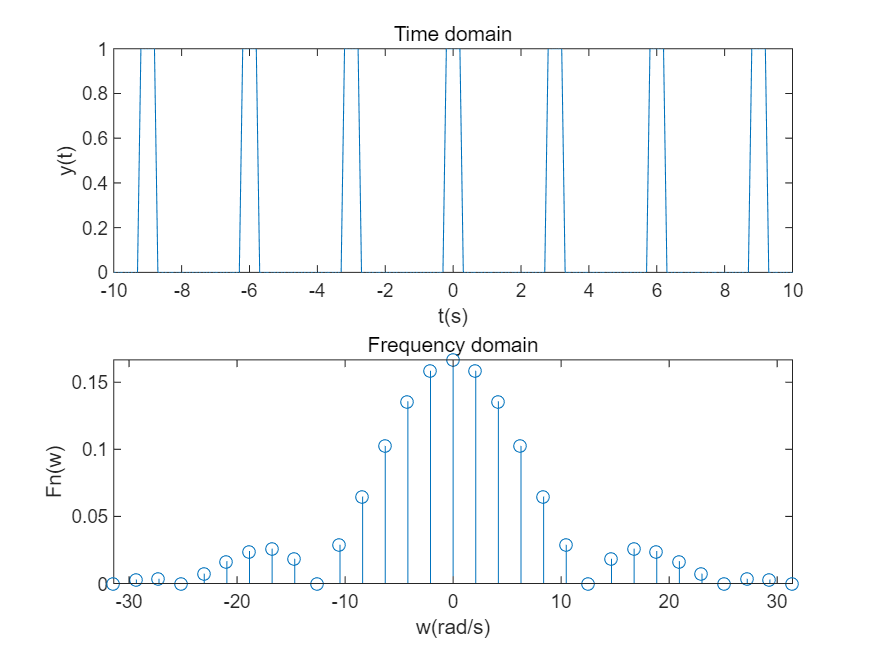

clear;clf;
dt = 0.1;
t = -10:dt:10;
T = 3;
tau = 0.5;
f = 0.5*(1+square(2*pi*(t+tau/2)/T,tau/T*100));
subplot(2,1,1);
plot(t,f);
axis([-10 10 -inf inf]);
title("Time domain");
xlabel("t(s)");
ylabel("y(t)");


N = 50;
n = -N:N;
w1 = 2*pi/T;
Wn = n*w1;
t_tau = -tau/2:dt:tau/2;
ft = 1;
F = ft.*exp(-j*n'*w1*t_tau);
Fn = trapz(t_tau,F,2)/T;
subplot(2,1,2);
stem(Wn,abs(Fn));
axis([-10*pi 10*pi -inf inf]);
title("Frequency domain");
xlabel("w(rad/s)");
ylabel("Fn(w)");

**Fourier Transform**

clear;clf;
syms t
a = 2;
f = exp(-(a*t))*heaviside(t);
subplot(3,1,1);
fplot(f);
axis([-3,3,-0.1,1.1]); grid on;
title("time domain");
xlabel("t(s)");
ylabel("f(t)");
F= fourier(f)

$$F = \frac{1}{2+w\,\mathrm{i}}$$

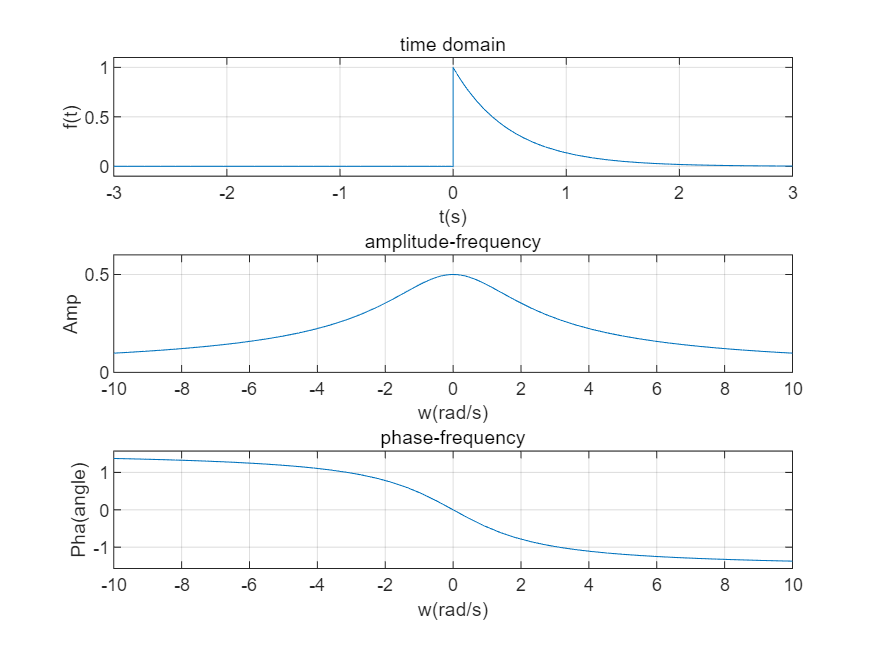


subplot(3,1,2);
fplot(abs(F));
axis([-10,10,0,0.6]); grid on;
title("amplitude-frequency");
xlabel("w(rad/s)");
ylabel("Amp");

subplot(3,1,3);
fplot(angle(F));
axis([-10,10,-pi/2,pi/2]); grid on;
title("phase-frequency"); xlabel("w(rad/s)");
ylabel("Pha(angle)");

inverse fourier transform

clear;clf;
syms t w
ifourier(1/(2+1j*w),t)

$$ans = \frac{{\mathrm{e}}^{-2\,t}\,\left(\mathrm{sign}\left(t\right)+1\right)}{2}$$

numeric method

fft for periodic signal

x = cos(2*pi*10*t)+2sin(2*pi*15*t)+3cos(2*pi*20*t)

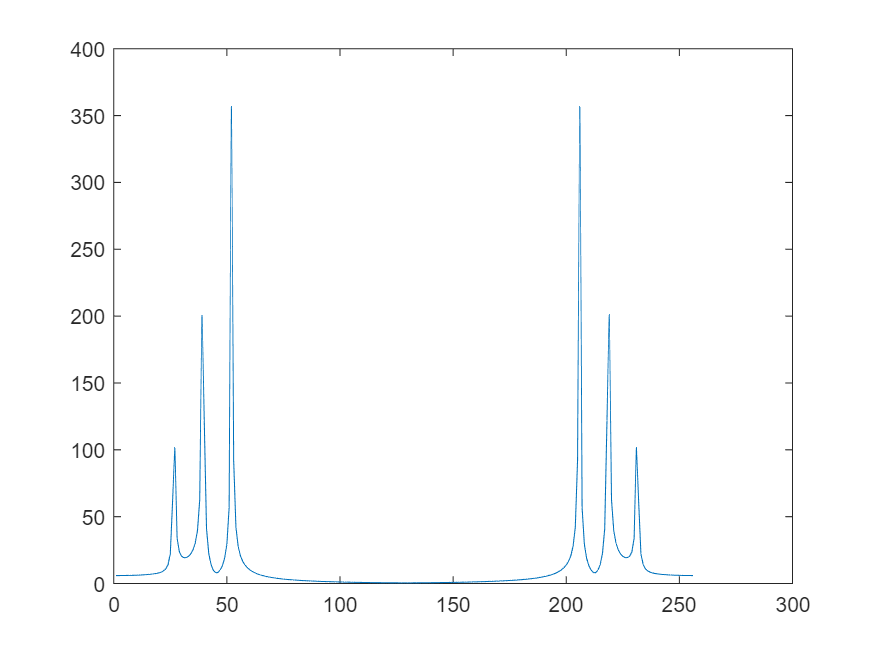

clear;clf;
N = 256;
Fs = 100;
dt = 1/Fs;
t = (0:N-1)*dt;
x = cos(2*pi*10.*t)+2*sin(2*pi*15.*t)+3*cos(2*pi*20.*t);
X = fft(x);
plot(abs(X));

Adjustment

x = cos(2*pi*10*t)+2sin(2*pi*15*t)+3cos(2*pi*20*t)

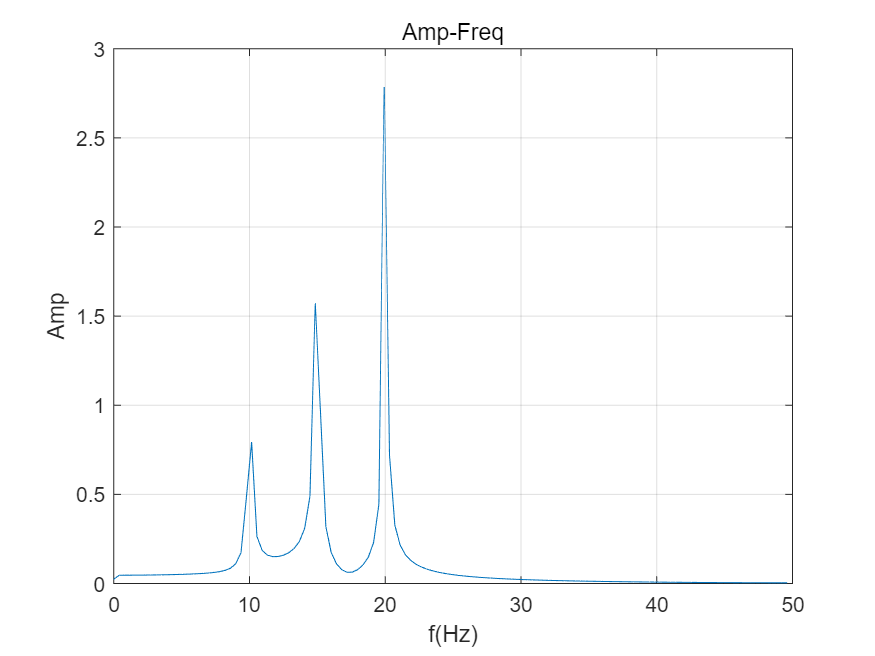

clear;clf;
N = 256;
Fs = 100;
dt = 1/Fs;
df = Fs/N;
t = (0:N-1)*dt;
f = (0:N-1)*df;
x = cos(2*pi*10.*t)+2*sin(2*pi*15.*t)+3*cos(2*pi*20.*t);
X = abs(fft(x))/N;
X = [X(1),2*X(2:N/2)];
f = f(1:N/2);
plot(f,X); grid on;
xlabel("f(Hz)");
ylabel("Amp");
title("Amp-Freq"); grid on;

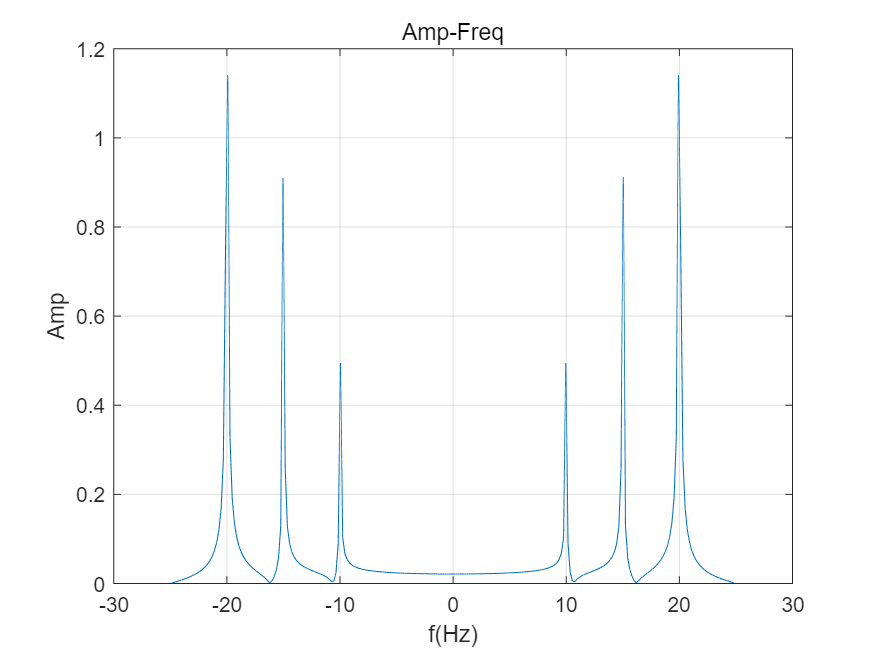



clear;clf;
N = 256;
Fs = 50;
dt = 1/Fs;
df = Fs/N;
t = (0:N-1)*dt;
x = cos(2*pi*10.*t)+2*sin(2*pi*15.*t)+3*cos(2*pi*20.*t);
X = fft(x);
Y = abs(fft(x))/N;
Yshift = fftshift(Y);
f = (-N/2:N/2-1)*df;
plot(f,Yshift);
xlabel("f(Hz)");
ylabel("Amp");
title("Amp-Freq"); grid on;

fft for aperiodic signal

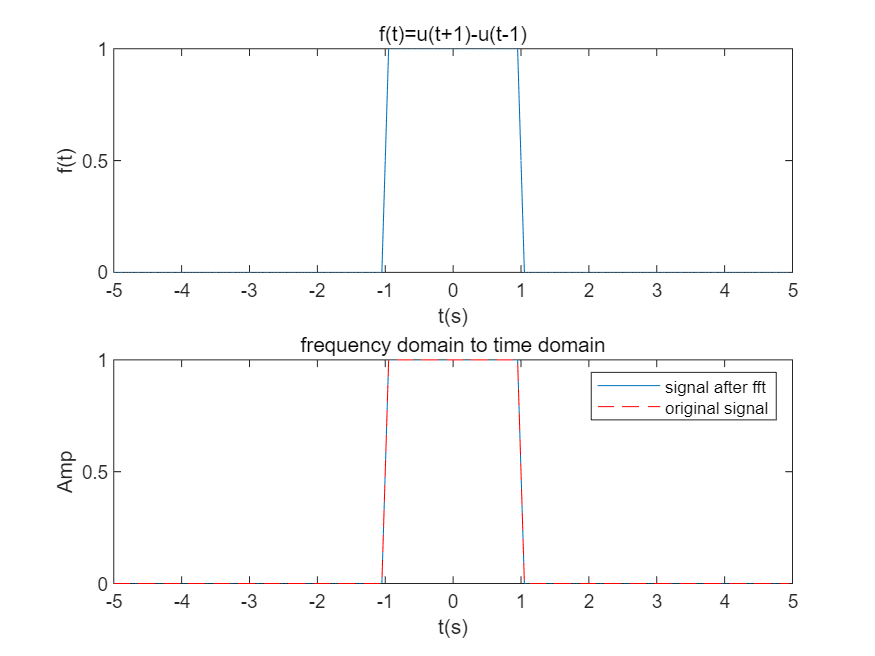

clear;clf;
dt = 0.05;
t = -5:dt:5-dt;
f = heaviside(t+1)-heaviside(t-1);
Fs = 1/dt;
N = length(t);
df = Fs/N;
F1 = fft(f,N);
F = abs(F1)*dt;
F = fftshift(F);
W = (-N/2:N/2-1)*df*2*pi;
subplot(2,1,1);
plot(t,f);
xlabel("t(s)");
ylabel("f(t)");
title("f(t)=u(t+1)-u(t-1)");

subplot(2,1,2);
plot(W,F);
xlabel("w(rad/s)");
ylabel("F(w)");
title("fft");

figure(1);
f1 = ifft(F1);
plot(t,f1,t,f,'r--');
xlabel("t(s)");
ylabel("Amp");
title("frequency domain to time domain");
legend("signal after fft","original signal");

spectrum leak

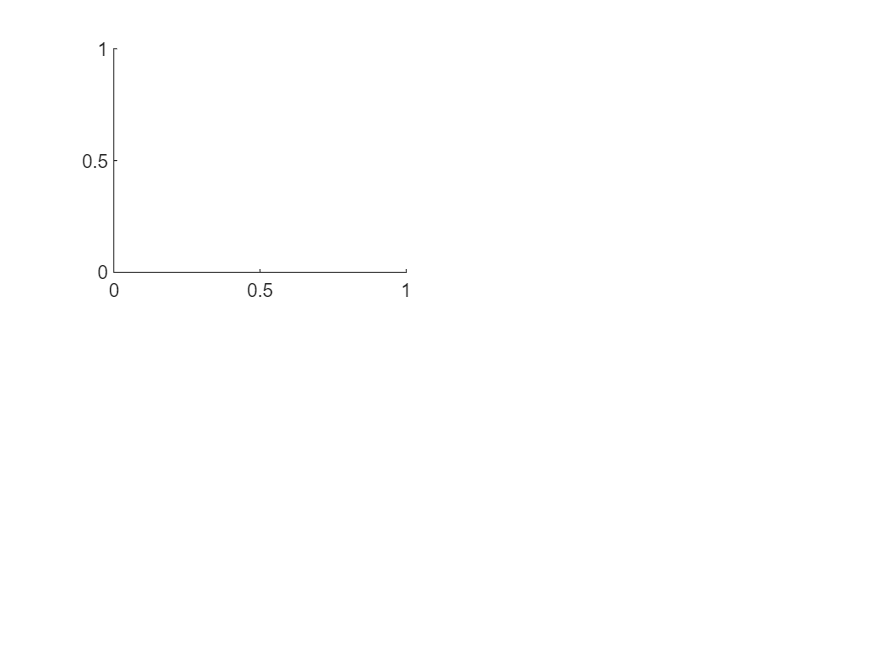

clear;clf;

N = 256; Fs = 120;
% what is this????
%[f, Yabs] = Lab4_frequenct_leak(N,Fs);
subplot(2,2,1);

%plot(f,Yabs);
%title("N=256,Fs=120");
%xlabel("f(Hz)");
%ylabel("Amplitude"); grid on;





matrix for  aperiodic signal

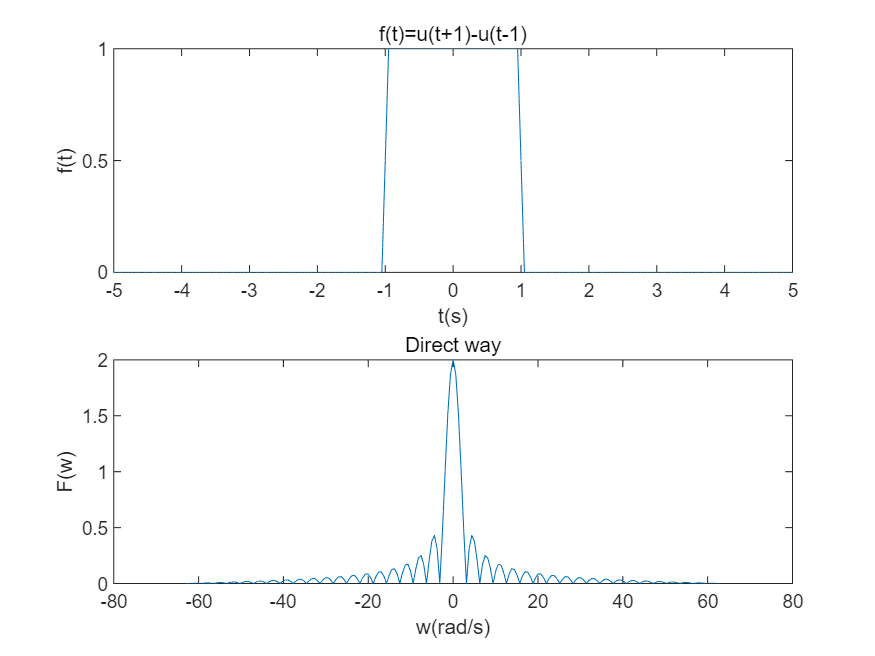

clear;clf;
dt = 0.05;
t = -5:dt:5;
f = heaviside(t+1)-heaviside(t-1);
M = 100;
k = -M:M;
W = 2*pi*10;
dw = W/M;
Wk = k*dw;
F = f*exp(-1j*t'*Wk)*dt;
F = abs(F);

subplot(2,1,1);
plot(t,f);
xlabel("t(s)");
ylabel("f(t)");
title("f(t)=u(t+1)-u(t-1)");

subplot(2,1,2);
plot(Wk,F);
xlabel("w(rad/s)");
ylabel("F(w)");
title("Direct way");

matrix for periodic signal

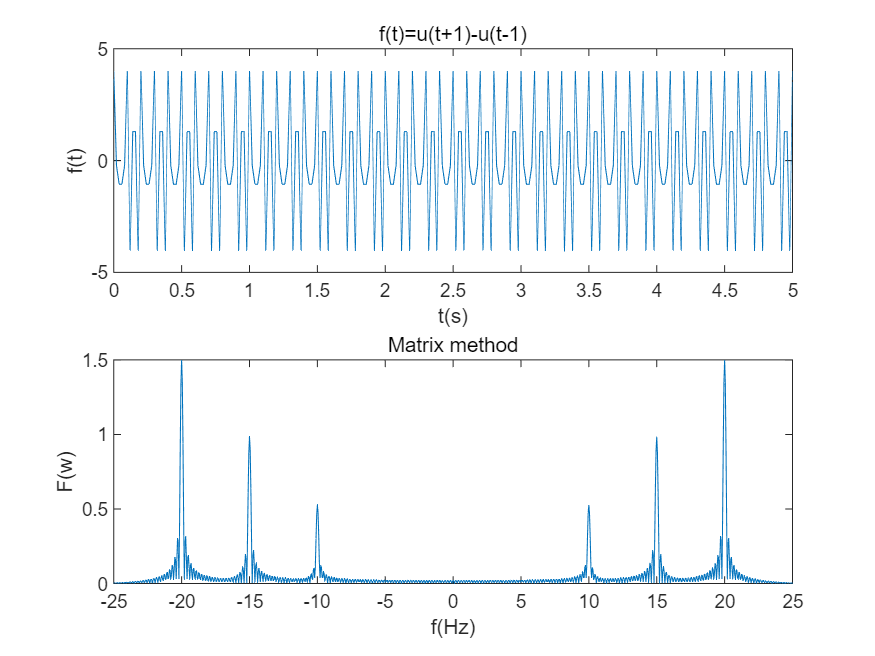

clear;clf;
N = 256;
Fs = 50;
dt = 1/Fs;
t = (0:N-1)/Fs;
f = cos(2*pi*10.*t)+2*sin(2*pi*15.*t)+3*cos(2*pi*20.*t);

M = 500;
k = -M:M;
f_range = Fs/2;
W = 2*pi*f_range;
dw = W/M;
Wk = k*dw;
F = f*exp(-1j*t'*Wk)*dt;
F = abs(F)/(t(end)-t(1));
subplot(2,1,1);
plot(t,f);
xlabel("t(s)");
ylabel("f(t)");
title("f(t)=u(t+1)-u(t-1)");
xlim([0 5]);

subplot(2,1,2);
plot(Wk/(2*pi),F);
xlabel("f(Hz)");
ylabel("F(w)");
title("Matrix method");